# 通信原理实验3

姓名：朱天昊

学号：18308267

邮箱：1312622783@qq.com

## 实验目标

`（1）模拟``AM调制``与``解调;`

`（2）模拟``FM调制``与``解调。`

## 实验条件

MATLAB 2016 and above, Simulink, and Communications System Toolbox .

## Prelab

## Problem 1  AM调制与解调

消息信号是[-3,3]均匀分布的随机整数，产生的时间间隔为1/10s，用AM方法调制载波$\cos \left(2\pi f_c t\right)$。假设$f_c =100,A_0 =4,0\le t\le 10$，试求： 

1）消息信号和已调信号的频谱；

2）已调信号的功率和调制效率；

3）用包络检波器解调该信号，画出原始信号和解调信号；

4）假设调制信号通过AWGN信道，信噪比为20dB，画出解调后的信号与原始信号。

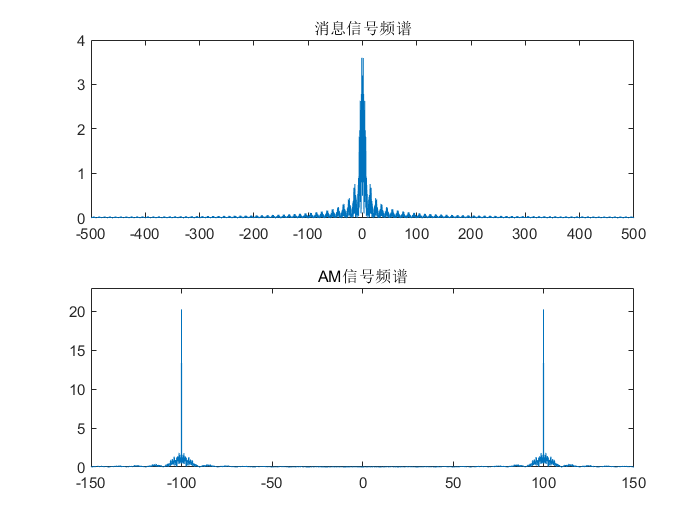

% insert your code
clear all; close all; clc;
% 第一问
ts = 0.001;                      %信号抽样时间间隔
t=0:ts:10-ts;                   %时间向量
fs = 1/ts;                        %抽样频率
df = fs/length(t);                %fft的频率采样间隔

mt = randi([-3,3], 100, 1);  %生成消息序列
mt1 = mt*ones(1,fs/10);         %扩展成取样信号形式
mt2 = reshape(mt1.',1,length(t));  % mt2就是从mt里面扩展的序列·
Pm = fft(mt2)/fs;                %求消息信号的频谱
f = -fs/2:df:fs/2-df; 
subplot(2,1,1)
plot(f,fftshift(abs(Pm)))       %画出消息信号频谱
title('消息信号频谱')

A=4;
fc=100;                         %载波频率
AM=(A+mt2).*cos(2*pi*fc*t);   %已调信号
Pam=fft(AM)/fs;                %已调信号频谱
subplot(2,1,2)
plot(f,fftshift(abs(Pam)))      %画出已调信号频谱
title('AM信号频谱')
axis([-150 150 0 23])

figure;

% 第二问
P = sum(abs(AM).^2)/length(AM);     %已调信号功率
Ps = P-A^2/2;                       %消息信号功率 
eff = Ps/P;                         %调制效率
fprintf('已调信号功率为%fW', P);

已调信号功率为10.215000W

fprintf('消息信号功率为%fW', Ps);

消息信号功率为2.215000W

fprintf('调制效率为%f', eff);

调制效率为0.216838

消息信号功率为4.030000W

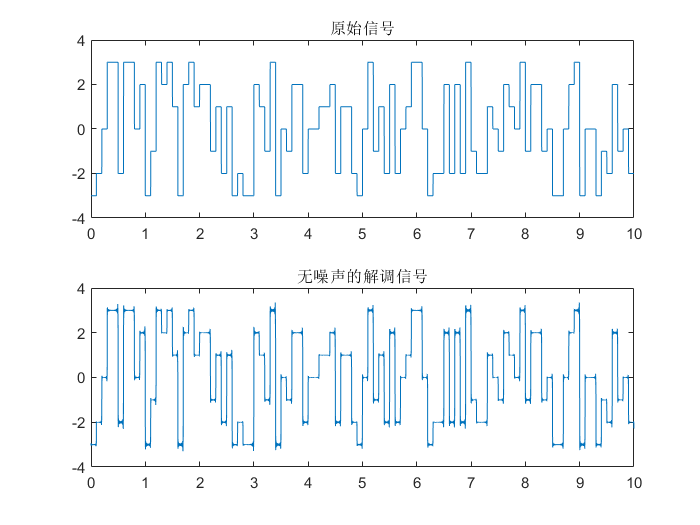

% 第三问
subplot(2,1,1);
plot(t, mt2);
title('原始信号');

subplot(2,1,2);
dm=abs(hilbert(AM))-A;       %包络检波，并且去掉直流分量。
plot(t,dm);                    %画出解调后的信号
title('无噪声的解调信号');

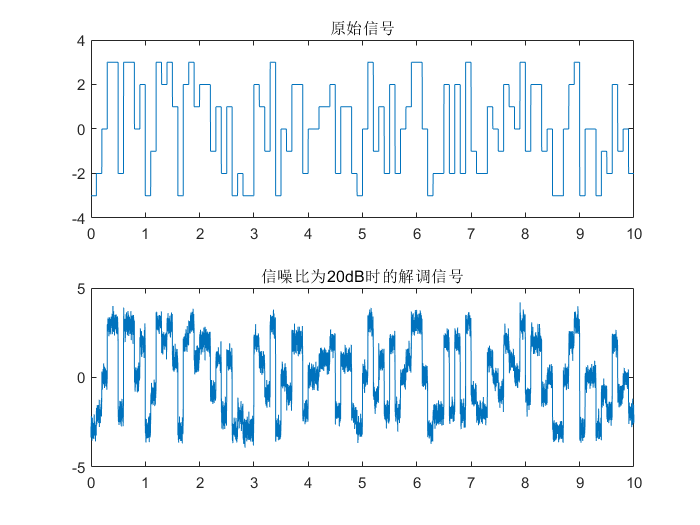

figure;

% 第四问
subplot(2,1,1);
plot(t, mt2);
title('原始信号');

subplot(2,1,2);
y=awgn(AM,20,'measured');      %调制信号通过AWGN信道
dm2=abs(hilbert(y))-A;        %包络检波步骤同上
plot(t,dm2);
title('信噪比为20dB时的解调信号');

## Lab

**Problem 1 DSB-SC调制与解调**

消息信号是[-3,3]均匀分布的随机整数，产生的时间间隔为1/10s，用DSB-SC方法调制载波$\cos \left(2\pi f_c t\right)$。假设$f_c =100,0\le t\le 10$，试求： 

1）消息信号和已调信号的频谱；

2）已调信号的功率和消息信号的功率；

3）用同步检波解调该信号，设低通滤波器的截止频率为100Hz，增益为2，画出原始信号和解调信号；

4）假设调制信号通过AWGN信道，信噪比为20dB，画出解调后的信号与原始信号。

**Answer:**

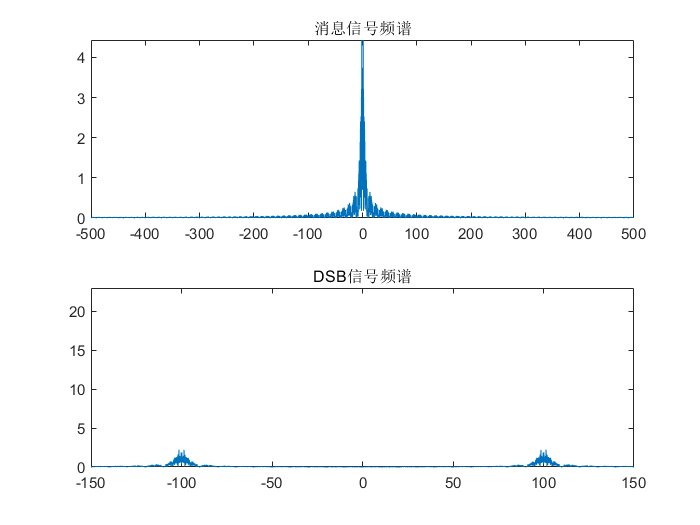

% insert your code here
clear all; close all; clc;
% 第一问
ts = 0.001;                      %信号抽样时间间隔
t = 0:ts:10-ts;                   %时间向量
fs = 1/ts;                        %抽样频率
df = fs/length(t);                %fft的频率分辨率

mt = randi([-3,3], 100, 1);  
mt1 = mt*ones(1,fs/10);         
mt2 = reshape(mt1.',1,length(t));
Pm = fft(mt2)/fs;               
f = -fs/2:df:fs/2-df; 

subplot(2,1,1)
plot(f,fftshift(abs(Pm)))       %画出消息信号频谱
title('消息信号频谱')

fc = 100;                         %载波频率
DSB = mt2.*cos(2*pi*fc*t);   %已调信号
Pam = fft(DSB)/fs;                %已调信号频谱
subplot(2,1,2)
plot(f,fftshift(abs(Pam)))      %画出已调信号频谱
title('DSB信号频谱')
axis([-150 150 0 23])

figure;

% 第二题
P = sum(abs(DSB).^2)/length(DSB);     %已调信号功率
Ps = sum(abs(mt2).^2)/length(mt2);    %消息信号功率         
fprintf('已调信号功率为%fW', P);

已调信号功率为2.185000W

fprintf('消息信号功率为%fW', Ps);

消息信号功率为4.370000W

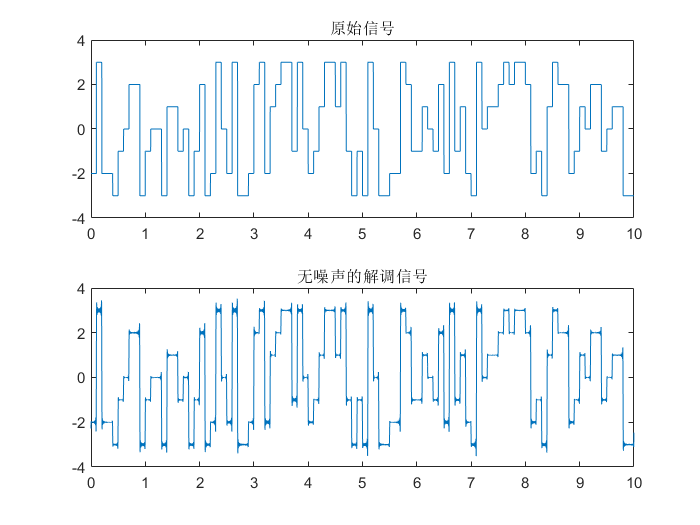



% 第三题
subplot(2,1,1);
plot(t, mt2);
title('原始信号');

subplot(2,1,2);
y = DSB.*cos(2*pi*fc*t);         %相干解调
Y = fft(y)./fs;                   %解调后的频谱
f_stop = 100;                     %低通滤波器的截止频率
n_stop = floor(f_stop/df);
Hlow = zeros(size(f));            %设计低通滤波器HLOW
Hlow(1:n_stop) = 2;
Hlow(length(f)-n_stop+1:end) = 2;
DEM = Y.*Hlow;                    %解调信号通过低通滤波器
dm = real(ifft(DEM))*fs;         %最终得到的解调信号
plot(t,dm);
title('无噪声的解调信号');

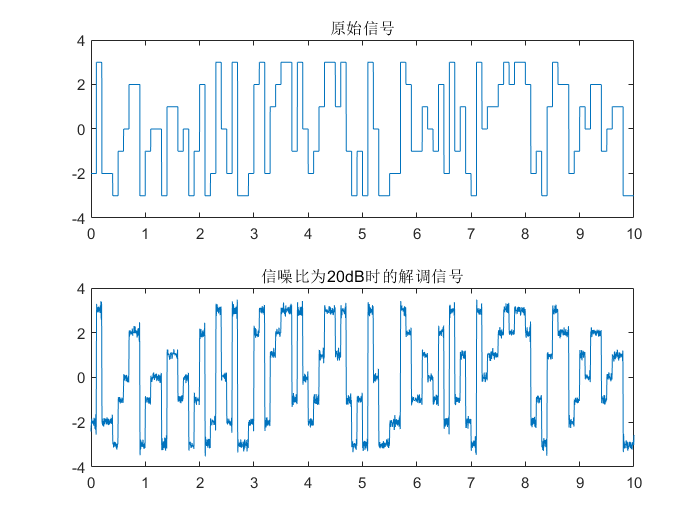

figure;

% 第四题
subplot(2,1,1);
plot(t, mt2);
title('原始信号');

subplot(2,1,2);
y1 = awgn(DSB,20,'measured');      %调制信号通过AWGN信道
y2 = y1.*cos(2*pi*fc*t);          %相干解调步骤同上
Y2 = fft(y2)./fs;                 
DEM1 = Y2.*Hlow;               
dm1 = real(ifft(DEM1))*fs;       
plot(t,dm1);
title('信噪比为20dB时的解调信号');

**仿真结果分析：**

1）DSB调制无载波分量，调制效率比AM高。

2）用同步检波的方法可以基本还原消息信号，误差较小。

3）调制信号通过AWGN信道后，解调信号会叠加一定的噪声扰动，严重时可影响信号的判决。

## Problem 2  FM调制与解调

消息信号是[-3,3]均匀分布的随机整数，产生的时间间隔为1/10s，用FM方法调制载波$\cos \left(2\pi f_c t\right)$。假设$f_c =250,k_f =50,0\le t\le 10$，消息信号的带宽为$W=50\textrm{Hz},$试求： 

1）消息信号和已调信号的频谱；

2）已调信号的功率、消息信号的功率、调制指数及调制信号的带宽；

3）用鉴频法解调该信号，画出原始信号和解调信号；

4）假设调制信号通过AWGN信道，信噪比为20dB，画出解调后的信号与原始信号。

**Answer:**

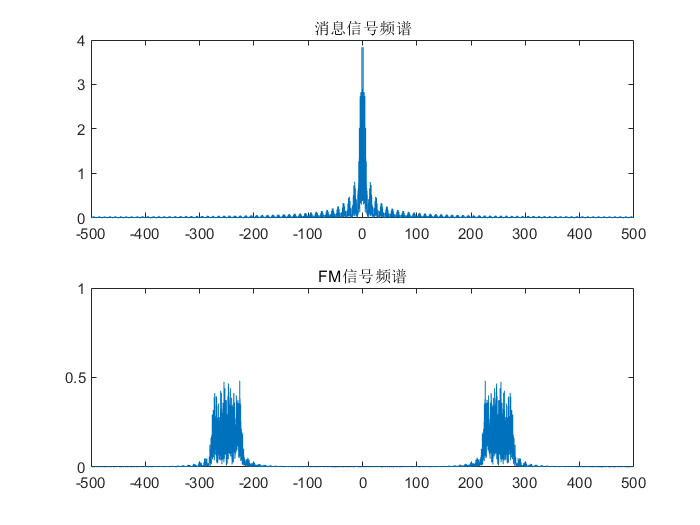

% insert your code here
clear all; close all; clc;
% 第一问
ts = 0.001;                      %信号抽样时间间隔
t = 0:ts:10-ts;                   %时间向量
fs = 1/ts;                        %抽样频率
df = fs/length(t);                %fft的频率分辨率

mt = randi([-3,3], 100, 1);  
mt1 = mt*ones(1,fs/10);         
mt2 = reshape(mt1.',1,length(t));
Pm = fft(mt2)/fs;                
f = -fs/2:df:fs/2-df; 

subplot(2,1,1)
plot(f,fftshift(abs(Pm)))       %画出消息信号频谱
title('消息信号频谱')

fc = 250;                         %载波频率
kf = 50;
int_mt(1)=0;                       %消息信号积分
for i=1:length(t)-1
    int_mt(i+1)=int_mt(i)+mt2(i)*ts;
end  
FM = cos(2*pi*fc*t+kf*int_mt);   %已调信号
Pam = fft(FM)/fs;                %已调信号频谱
subplot(2,1,2)
plot(f,fftshift(abs(Pam)))      %画出已调信号频谱
title('FM信号频谱')
axis([-500 500 0 1.0])

figure;

% 第二问
fm = 50;
P = sum(abs(FM).^2)/length(FM);   %已调信号功率
Ps = sum(abs(mt2).^2)/length(mt2);  %消息信号功率
mf = kf*max(mt2) / fm;           % 调制信号mt2的频率要怎么表示
B = 2*(mf+1)*fm;
fprintf('已调信号功率为%fW', P);

已调信号功率为0.499974W

fprintf('消息信号功率为%fW', Ps);

消息信号功率为4.000000W

fprintf('调频指数%f', mf);

调频指数3.000000

fprintf('带宽%fW', B);

带宽400.000000W

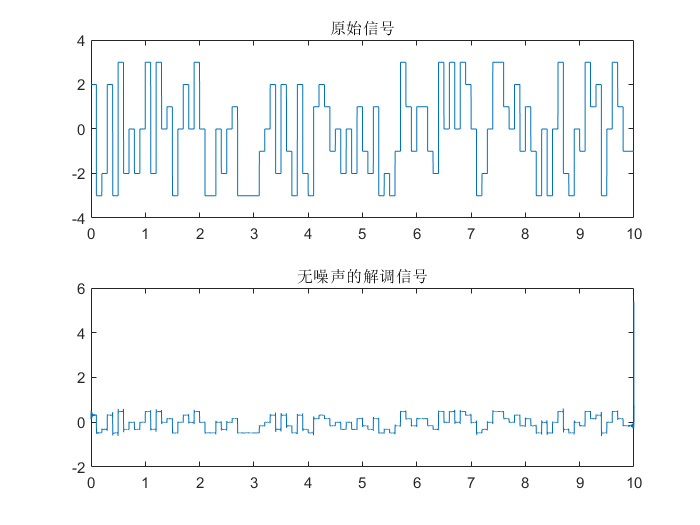



% 第三问
subplot(2,1,1);
plot(t, mt2);
title('原始信号');

phase=angle(hilbert(FM).*exp(-j*2*pi*fc*t));   %FM调制信号相位
phi=unwrap(phase);                              
dem=(1/(2*pi*kf)*diff(phi)/ts);                 %求相位微分，得到消息信号
dem(length(t))=0;
subplot(2,1,2)
plot(t,dem);
title('无噪声的解调信号')

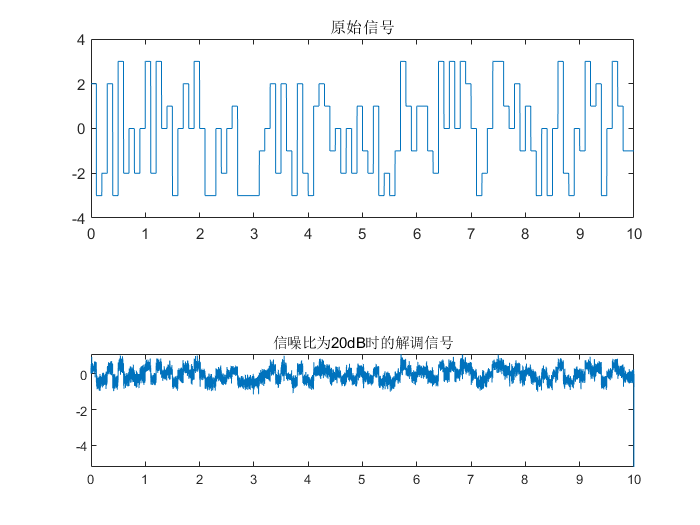

figure;

% 第四问
subplot(2,1,1);
plot(t, mt2);
title('原始信号');

y1=awgn(FM,20,'measured');             %调制信号通过AWGN信道
y1(find(y1>1))=1;                       %调制信号限幅
y1(find(y1<-1))=-1;
phase1=angle(hilbert(y1).*exp(-j*2*pi*fc*t));   %信号解调
phi1=unwrap(phase1);
dem1=(1/(2*pi*kf)*diff(phi1)/ts);
dem1(length(t))=0;
subplot(3,1,3)
plot(t,dem1);
title('信噪比为20dB时的解调信号')

**仿真结果分析：**

1）FM调制的频谱比AM、DSB都要宽，但由解调信号的波形可以看出，FM调制的信噪比更小。

2）FM调制信号的带宽与调制信号的振幅成正比，与调制信号的角频率成反比。

3）FM调制信号在通过AWGN信道后，也会在解调输出端叠加一定的扰动。

## **Postlab**

消息信号是[-3,3]均匀分布的随机整数，产生的时间间隔为1/10s，用移相法调制载波$\cos \left(2\pi f_c t\right)$，形成USSB信号。假设$f_c =100,0\le t\le 10$，试求： 

1）消息信号和已调信号的频谱；

2）已调信号的功率和消息信号的功率；

3）用同步检波解调该信号，设低通滤波器的截止频率为100Hz，增益为4，画出原始信号和解调信号；

4）假设调制信号通过AWGN信道，信噪比为20dB，画出解调后的信号与原始信号。

**Answer:**

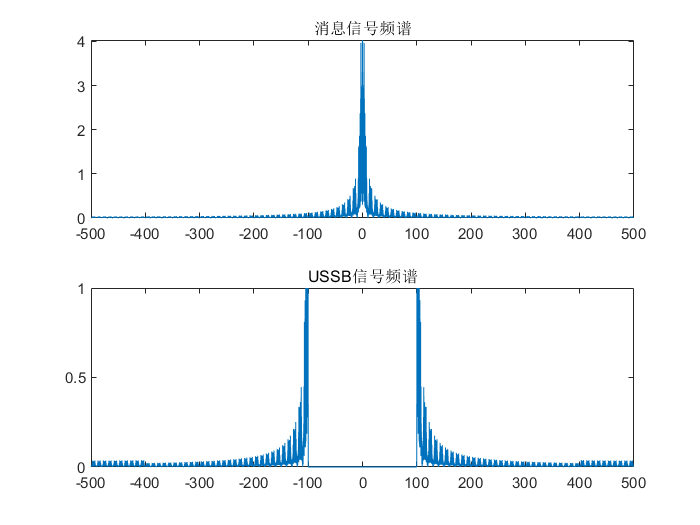

% insert your code here
clear all; close all; clc;
% 第一问
ts = 0.001;                      %信号抽样时间间隔
t = 0:ts:10-ts;                   %时间向量
fs = 1/ts;                        %抽样频率
df = fs/length(t);                %fft的频率分辨率

mt = randi([-3,3], 100, 1);  
mt1 = mt*ones(1,fs/10);         
mt2 = reshape(mt1.',1,length(t));
Pm = fft(mt2)/fs;                
f = -fs/2:df:fs/2-df; 

subplot(2,1,1)
plot(f,fftshift(abs(Pm)))       %画出消息信号频谱
title('消息信号频谱')

fc = 100;                         %载波频率
s1 = 0.5*mt2.*cos(2*pi*fc*t);    %USSB信号的同相分量
hmt2 = imag(hilbert(mt2));       %消息信号的Hilbert变换
s2 = 0.5*hmt2.*sin(2*pi*fc*t);    %USSB信号的正交分量
USSB = s1-s2;                    %完整的USSB信号
subplot(2,1,2);
Pam = fft(USSB)/fs;
plot(f,fftshift(abs(Pam)))      %画出已调信号频谱
title('USSB信号频谱')
axis([-500 500 0 1.0])

figure;

% 第二问
P = sum(abs(USSB).^2)/length(USSB);     %已调信号功率
Ps = sum(abs(mt2).^2)/length(mt2);    %消息信号功率         
fprintf('已调信号功率为%fW', P);

已调信号功率为1.009203W

fprintf('消息信号功率为%fW', Ps);

消息信号功率为4.030000W

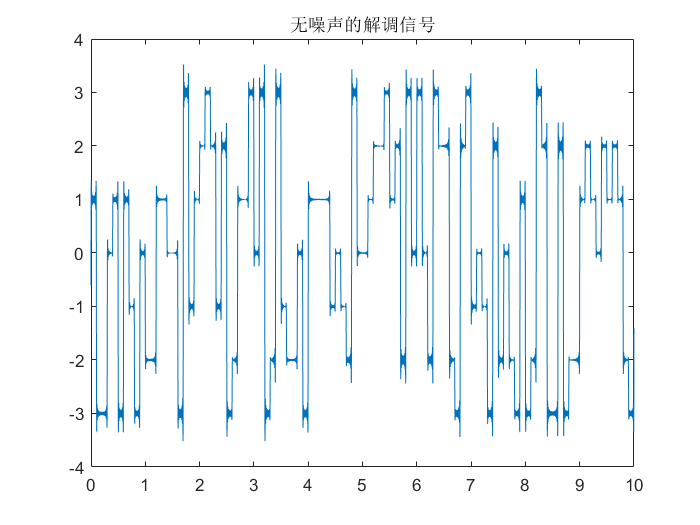


% 第三问
y=USSB.*cos(2*pi*fc*t);        %相干解调
Y=fft(y)./fs;                   %解调后的频谱
f_stop=100;                     %低通滤波器的截止频率
n_stop=floor(f_stop/df);
Hlow=zeros(size(f));            %设计低通滤波器
Hlow(1:n_stop)=4;
Hlow(length(f)-n_stop+1:end)=4;
DEM=Y.*Hlow;                    %解调信号通过低通滤波器
dem=real(ifft(DEM))*fs;         %最终得到的解调信号
plot(t,dem);
title('无噪声的解调信号')

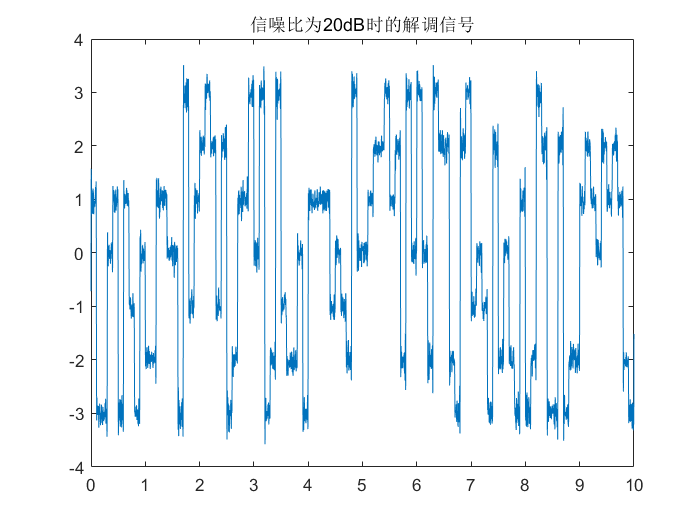


% 第四问
y1=awgn(USSB,20,'measured');    %调制信号通过AWGN信道
y2=y1.*cos(2*pi*fc*t);          %相干解调
Y2=fft(y2)./fs;                 %解调信号的频谱
DEM1=Y2.*Hlow;                  %解调信号通过低通滤波器
dem1=real(ifft(DEM1))*fs;       %最终得到的解调信号
plot(t,dem1)
title('信噪比为20dB时的解调信号')

**仿真结果分析：**

1）USSB信号的带宽是所有调制方式中最少的，其频带利用率较高。

2）在USSB调制中，由于只用到一个边带，所以在消息信号功率相同情况下，已调信号的功率是是DSB的一半。

3）USSB调制信号在通过AWGN信道后，会在解调输出端叠加一定的扰动。

## 实验总结

通过这次实验，掌握了幅度调制/解调和频率调制/解调的原理，回答了关于……的问题……。

## 答：通过这次实验，我进一步掌握了各种调制方式的频谱特性、它们的功率关系以及它们的优缺点和使用场景。AM调制是最简单的调制，但抗噪声性能差，频带利用率也不高。DSB和SSB在此基础上分别提取出消息信号的边带以减小带宽；FM调制的抗噪声性能最强，但其带宽最大，在实际使用场景需权衡。